# enae432 hw10

vai srivastava

## problem 1

s  = zpk('s');

### part b

n = 2;
eta = [ 0.01, 0.005 ];
omega = [ 4, 15 ];
rho = [ 0.04, 0.04 ];
I = 50;

G = (I*s^2*(1-s^2*(rho(1)*(s^2+2*eta(1)*omega(1)*s+omega(1)^2)^-1+rho(2)*(s^2+2*eta(2)*omega(2)*s+omega(2)^2)^-1)))^(-1)


G =
 
    0.021739 (s^2 + 0.08s + 16) (s^2 + 0.15s + 225)
  ----------------------------------------------------
  s^2 (s^2 + 0.08331s + 16.66) (s^2 + 0.1567s + 234.8)
 
Continuous-time zero/pole/gain model.
Model Properties


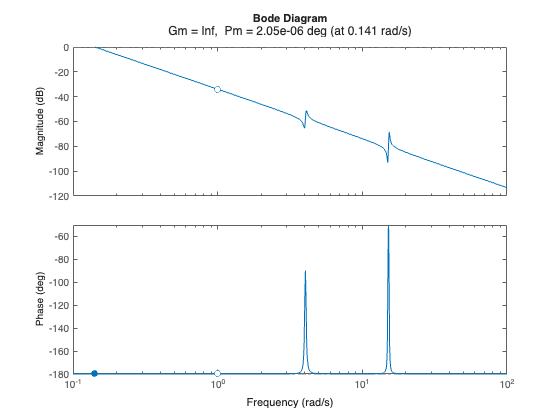

margin(G)

### part d

syms alpha_sym K_sym;

omega_c = 0.4;
phi_max = deg2rad(50);

alpha = double(solve(phi_max == asin((1-alpha_sym)/(1+alpha_sym)), alpha_sym))

alpha = 0.1325

tau = 1/(omega_c*sqrt(alpha))

tau = 6.8687


K = double(solve(1 == abs(K_sym*(tau*omega_c*1j)/(I*(omega_c*1j)^2*(alpha*tau*omega_c*1j+1))), K_sym))

K = 3.0986


G_0 = 1/(I*s^2)


G_0 =
 
  0.02
  ----
  s^2
 
Continuous-time zero/pole/gain model.
Model Properties


H_0 = K*(tau*s+1)/(alpha*tau*s+1)


H_0 =
 
  23.39 (s+0.1456)
  ----------------
     (s+1.099)
 
Continuous-time zero/pole/gain model.
Model Properties


L_0 = H_0*G_0


L_0 =
 
  0.46781 (s+0.1456)
  ------------------
    s^2 (s+1.099)
 
Continuous-time zero/pole/gain model.
Model Properties


T_0 = feedback(L_0, 1)


T_0 =
 
          0.46781 (s+0.1456)
  -----------------------------------
  (s+0.2959) (s^2 + 0.8031s + 0.2302)
 
Continuous-time zero/pole/gain model.
Model Properties


stepinfo(T_0)

ans = struct with fields:
         RiseTime: 2.6351
    TransientTime: 17.4347
     SettlingTime: 17.4347
      SettlingMin: 0.9139
      SettlingMax: 1.2789
        Overshoot: 27.8858
       Undershoot: 0
             Peak: 1.2789
         PeakTime: 7.0038


## problem 2

### part a

L = H_0*G


L =
 
    0.50849 (s+0.1456) (s^2 + 0.08s + 16) (s^2 + 0.15s + 225)
  --------------------------------------------------------------
  s^2 (s+1.099) (s^2 + 0.08331s + 16.66) (s^2 + 0.1567s + 234.8)
 
Continuous-time zero/pole/gain model.
Model Properties


T = feedback(L, 1)


T =
 
               0.50849 (s+0.1456) (s^2 + 0.08s + 16) (s^2 + 0.15s + 225)
  -----------------------------------------------------------------------------------
  (s+0.2957) (s^2 + 0.8021s + 0.2301) (s^2 + 0.0844s + 16.68) (s^2 + 0.1568s + 234.8)
 
Continuous-time zero/pole/gain model.
Model Properties


stepinfo(T)

ans = struct with fields:
         RiseTime: 2.6441
    TransientTime: 17.4976
     SettlingTime: 17.4976
      SettlingMin: 0.9142
      SettlingMax: 1.2797
        Overshoot: 27.9669
       Undershoot: 0
             Peak: 1.2797
         PeakTime: 7.0086


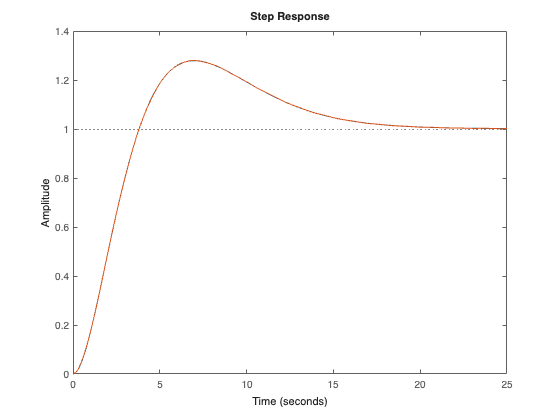

stepplot(T_0, T)

### part b

w = logspace(-2,2,1000);
[magG,~]  = bode(G, w);  magG  = squeeze(magG);
[magG_0,~] = bode(G_0,w);  magG_0 = squeeze(magG_0);

Delta = (magG./magG_0) - 1;

[magL_0,~] = bode(H_0*G_0, w);  magL_0 = squeeze(magL_0);
T_0jw = magL_0 ./ (1 + magL_0);

M = abs(Delta).*T_0jw;
[Msup,idx] = max(M)

Msup = 0.0347

idx = 654

wsup = w(idx)

wsup = 4.1173

sup_ω |Δ·T0| = 3.471e-02  at  ω = 4.12  rad/s


### part c

idx1 = find( abs(w-4)==min(abs(w-4)), 1 );
d1 = Delta(idx1);
omega_c_max = 4/sqrt(abs(d1))

omega_c_max = 5.5126

### part d

Td = feedback(G, 1+L);

magTd = squeeze(bode(Td,w));

mask = magTd <= 0.1;
w_mask = w(mask);
low_freq_end  = max(w_mask(w_mask<0.4))

low_freq_end = 0.1876

high_freq_start = min(w_mask(w_mask>0.4))

high_freq_start = 0.4422

### part e

Tnoise = feedback(L,1);
magTnoise = squeeze(bode(Tnoise,w));

mask_n = magTnoise <= 0.1;
noise_cut = min(w(mask_n))

noise_cut = 2.1200

## problem 3

### part a

syms K_sym;
s_0 = -2+3j;

z = -1*(2+3/tan(deg2rad(180)+atan(3/-2)+pi+3*atan(3/3)))

z = -2.6000

K = double(solve(1 == abs(4*K_sym*(s_0-z)/(s_0*(s_0+5)^3)), K_sym))

K = 22.5000

### part b

L = 4*K*(s-z)/(s*(s+5)^3)


L =
 
  90 (s+2.6)
  ----------
  s (s+5)^3
 
Continuous-time zero/pole/gain model.
Model Properties


T = feedback(L, 1)


T =
 
          90 (s+2.6)
  ---------------------------
  (s+9) (s+2) (s^2 + 4s + 13)
 
Continuous-time zero/pole/gain model.
Model Properties


pole(T)

ans =   -9.0000 + 0.0000i
  -2.0000 + 3.0000i
  -2.0000 - 3.0000i
  -2.0000 + 0.0000i


### part c

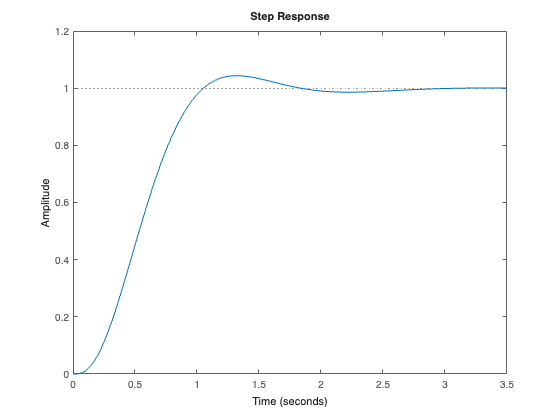

step(T)

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.6382
    TransientTime: 1.6284
     SettlingTime: 1.6284
      SettlingMin: 0.9031
      SettlingMax: 1.0435
        Overshoot: 4.3489
       Undershoot: 0
             Peak: 1.0435
         PeakTime: 1.3201


### part d

K_new = K*7

K_new = 157.5000

L_new = 4*K_new*(s-z)/(s*(s+5)^3)


L_new =
 
  630 (s+2.6)
  -----------
   s (s+5)^3
 
Continuous-time zero/pole/gain model.
Model Properties


T_new = feedback(L_new, 1)


T_new =
 
                 630 (s+2.6)
  ------------------------------------------
  (s+12.96) (s+2.54) (s^2 - 0.4958s + 49.78)
 
Continuous-time zero/pole/gain model.
Model Properties


pole(T_new)

ans =  -12.9559 + 0.0000i
   0.2479 + 7.0508i
   0.2479 - 7.0508i
  -2.5400 + 0.0000i
